# Model Coherent on Receive Monostatic Tx and Rx

Construct a rectangular pulse waveform with five pulses. The PRF is 10 kHz and the pulse width is 50 microseconds. The PRI is exactly two times the pulse width so the transmitter alternates between active and inactive time intervals of the same duration.

wav = phased.RectangularWaveform("NumPulses",5);
wf = wav();

In a monostatic radar, the transmitter and receiver cannot operate simultaneously. Enable the PhaseNoiseOutputPort and InUseOutputPort properties on the transmitter to record the phase noise and the status of the transmitter.

Tx = phased.Transmitter("CoherentOnTransmit",false,...
    "PhaseNoiseOutputPort",true,"InUseOutputPort",true,...
    "SeedSource","Property","Seed",1000);
[sig,txstatus,phnoise] = Tx(wf);

Delay signal by one pulse width to acquire signal when receiver is on.

sig = delayseq(sig,wav.PulseWidth,wav.SampleRate);

In a coherent on receive radar, the receiver corrects for the phase noise introduced at the transmitter by using the record of those phase errors. Enable the EnableInputPort property on the Receiver object to determine when the receiver is active.  Then, after the RF chain correct for the phase noise introduced at the transmitter.

Rx = phased.Receiver("Gain",0,"EnableInputPort",true);
yWPhaseNoise = Rx(sig,~txstatus);
% Compensate for phase noise after RF chain
y = yWPhaseNoise .* exp(-1i*phnoise);

Plot Tx and Rx Signals

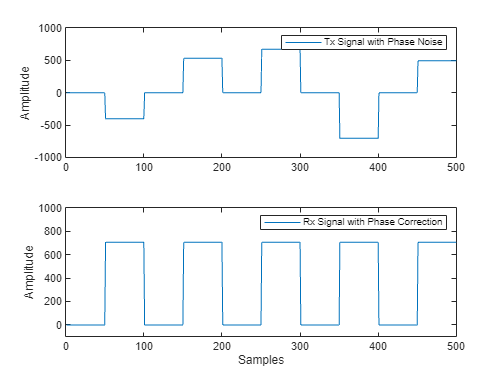

subplot(2,1,1)
plot(real(sig));
legend("Tx Signal with Phase Noise");
ylabel("Amplitude");
subplot(2,1,2)
plot(real(y));
ylim([-100 1000])
xlabel("Samples"); ylabel("Amplitude");
legend("Rx Signal with Phase Correction");